# MATLAB FOR BEGINNERS (Complete Code)

## MODULO 1 (BASI)

### 1.1: Default layout e Command Window

*Questa sezione non contiene codice: verrà tutto svolto nella Command Window*

Il layout di default contiene tre pannelli: **Current Folder** (sx), **Command Window** (cx), **Workspace** (dx).

Puoi eseguire comandi scrivendoli nella **Command Window** dopo il simbolo di prompt (>>) e premento il tasto **Invio**. A meno che non venga specificata una variabile di Output, il valore viene salvato in una variabile chiamata Ans. Sono presenti tutte le operazioni standard (+, -, *, /, ^)

Il simbolo (=) in MATLAB è un operatore di *assegnamento*, che assegna l'espressione a destra alla variabile a sinistra. Nota che nella finestra **Workspace** vengono salvate tutte le variabili create, e scrivendo solo il nome della variabile ne verrà mostrato il valore attuale. Puoi chiamare le tue variabili come vuoi, a patto che inizino con una lettera e contengano solo lettere, numeri e underscores (_). Le variabili sono anche Case Sensitive: ad esempio, *Apple* è diverso da *apple*.

Se aggiungi un **punto e virgola** (;) alla fine del comando, il risultato non verrà stampato ma il comando sarà eseguito lo stesso, come puoi vedere nel Workspace. Puoi richiamare comandi scritti in precedenza premendo il tasto Su ↑ sulla tastiera quando il tuo cursore è attivo nella Command Window.

Quando inizi a lavorare su un nuovo problema è buona pratica **ripulire il Workspace**: utilizza il comando *clear all* per eliminare tutte le variabili salvate, e il comando *clc* per pulire la Command Window

### 1.2 Live Editor

Inserire i comandi nella command window è un modo veloce per fare delle prove e vedere i risultati, ma risolvere problemi spesso richiede molte righe di codice e comandi.

Potete salvare le righe di codice e gli output insieme creando un **live script**: clicca in alto su *New Live Script* nella Home Tab per crearne uno.

Il live script è uno strumento molto potente: puoi inserire i comandi nell’**area grigia**, cambiare in **testo** (Text) per aggiungere descrizioni, e cliccare su **run** per eseguire tutto il live script. L’output viene salvato a destra, ma puoi cambiare il layout. Puoi anche dividere il tuo codice in sezioni (*Section Break*), per eseguire solo una porzione di codice per volta con “Run section”. Cliccando sul codice verrà evidenziato l'output corrispondente e viceversa.

Cliccando su *Save* puoi salvare il codice, ouput e testo, sia in formato nativo (*.mlx*) che in pdf. Da ora in avanti useremo il Live Script, e ti incoraggiamo a fare lo stesso quando userai MATLAB in futuro!

Prima di cominciare, scriviamo i tre comandi che resettano l'ambiente. 

- `clc`: pulisce la Command Window

- `clear all: `cancella tutte le variabili salvate

- `close all:` chiude tutte le figure aperte

### 1.3 Costanti e funzioni built-in 

MATLAB contiene alcune **costanti** built-in, come pi per rappresentare *π, *utilizzando il comando *exp(k) *puoi rappresentare e^k.

pi

ans = 3.1416

exp(1)  % Numero di nepero

ans = 2.7183

x = pi/2

x = 1.5708

MATLAB contiene anche un numero pressoché sterminato di funzioni built-in (se hai bisogno di qualcosa, *molto probabilmente* è già stato implementato): eccone alcune matematiche di base

% Seno, coseno, tangente
y = sin(x)

y = 1

y = cos(x)

y = 6.1232e-17

z = tan(x)

z = 1.6331e+16


% Arcoseno, arcocoseno, arcotangente
asin(1)

ans = 1.5708

acos(1)

ans = 0

atan(1)

ans = 0.7854


% Esponenziale, logaritmo in base e, 2, 10
exp(2) % e^2

ans = 7.3891

log(1) % ln(1)

ans = 0

log2(4)

ans = 2

log10(10^3)

ans = 3


% Radice quadrata, valore assoluto
sqrt(-9)

ans = 0.0000 + 3.0000i

abs(-4)

ans = 4


% Approssimazione a numeri interi
ceil(0.4)

ans = 1

floor(2.6)

ans = 2

fix(3.4)

ans = 3

round(4.4)

ans = 4

Nota che per passare un input alle funzioni vengono utilizzate le parentesi tonde. 

NB: Il nunero immaginario *i* è anch'esso una costante built-in. `cos(pi/2) `e` tan(pi/2) `non hanno restituito i valori attesi, 0 e infinito. Questo è dovuto ad errori di approssimazione nel calcolo coi decimali: esiste un pacchetto apposito per questo tipo di calcoli, chiamato **Symbolic Toolbox**, che vedremo più avanti. 

NB2: È comparso un warning, ma il codice verrà eseguito lo stesso. Cliccando sul triangolino giallo puoi vedere la linea che causa problemi, oltre a suggerimenti utili per ottimizzarlo. Se l'icona è rossa, c'è un errore nel codice e l'esecuzione verrà interrotta.

Solo le prime 4 cifre decimali vengono mostrate nell'output. Se serve più precisione, puoi utilizzare i comandi *format.*

format long
x

x =    1.570796326794897


format short
x

x = 1.5708

## MODULO 2 (Arrays, Matrici e Indexing)

### 2.1: Creazione di array

*MATLAB* è un'abbreviazione di "matrix laboratory", "laboratorio di matrici". Mentre altri linguaggi di programmazione lavorano principalmente su un numero per volta, MATLAB consente di operare soprattutto su intere matrici e array.

Tutte le variabili di MATLAB sono *array* multidimensionali, indipendentemente dal tipo di dati. Una *matrice* è un array bidimensionale frequentemente utilizzato nell'algebra lineare.

Un numero singolo, chiamato *scalare*, è salvato in MATLAB come un array 1x1, contenente una riga e una colonna.

Puoi creare array con elementi multipli usando le parentesi quadre: separando i numeri con spazi viene creato un vettore **riga **(1xn), separando i numeri col punto e virgola vengono creati vettori **colonna **(nx1)

x = [3 5]

x =      3     5


y = [3;5]

y =      3
     5


Combinando spazi e ; puoi creare una matrice, un array bidimensionale. L'inserimento avviene per righe. Puoi anche fare operazioni all'interno delle parentesi quadre

z = [1 2 3;4 5 6;7 sqrt(2) pi^2]

z =     1.0000    2.0000    3.0000
    4.0000    5.0000    6.0000
    7.0000    1.4142    9.8696


Inserire manualmente i valori può diventare scomodo. Spesso (come vedremo nel modulo 3) sono necessari dei **vettori equispaziati**, come:

y = [5 6 7 8]

y =      5     6     7     8


Esistono comandi per creare rapidamente vettori simili, come* l'operatore :*

`partenza:passo:arrivo`

y = 5:8 % se non viene specificato, il passo è 1

y =      5     6     7     8


x = 1:10

x =      1     2     3     4     5     6     7     8     9    10


z = 3:2:13

z =      3     5     7     9    11    13


Se invece sai già il numero di elementi che vuoi in un vettore (la sua lunghezza), puoi usare la funzione *linspace*

`linspace(primo el,ultimo el,numero di elementi)`

x = linspace(0,1,5) % 5 punti equispaziati tra 0 e 1

x =          0    0.2500    0.5000    0.7500    1.0000


y = linspace(1, 2*pi, 100)

y =     1.0000    1.0534    1.1067    1.1601    1.2135    1.2668    1.3202    1.3736    1.4269    1.4803    1.5337    1.5870    1.6404    1.6938    1.7471    1.8005    1.8538    1.9072    1.9606    2.0139    2.0673    2.1207    2.1740    2.2274    2.2808    2.3341    2.3875    2.4409    2.4942    2.5476    2.6010    2.6543    2.7077    2.7611    2.8144    2.8678    2.9212    2.9745    3.0279    3.0813    3.1346    3.1880    3.2414    3.2947    3.3481    3.4014    3.4548    3.5082    3.5615    3.6149


Sia : che *linspace* creano vettori riga. Se necessiti di un vettore colonna puoi utilizzare l'operatore apostrofo (*') *per effettuare una trasposizione

x = 1:3

x =      1     2     3


x = x'

x =      1
     2
     3



y = linspace(0, 2*pi, 100)' % puoi usare ' nella creazione

y =          0
    0.0635
    0.1269
    0.1904
    0.2539
    0.3173
    0.3808
    0.4443
    0.5077
    0.5712


x = (1:2:5)' % le parentesi specificano l'ordine delle operazioni

x =      1
     3
     5


Esistono molte funzioni per la generazione di array e matrici. Alcune tra le più utili sono:

X = ones(2,3) 

X =      1     1     1
     1     1     1


Y = zeros(4)

Y =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


Z = rand(2)

Z =     0.9575    0.1576
    0.9649    0.9706


%% Ricordati di usare help o doc se non sai come usare una funzione!!

### 2.2: Indexing

Dato che tutto le variabili in MATLAB sono array, è fondamentale imparare come usarli, come riferirsi a elementi specifici per estrarre o modificare valori: in altre parole, come effettuare l'**indexing**.

La posizione di un valore in un array è chiamata *indice*. Puoi usare l'indice per modificare o estrarre il valore, per esempio, se vuoi il terzo elemento del vettore:

x = 1:10

x =      1     2     3     4     5     6     7     8     9    10


x(3) % estrarre il valore del terzo el

ans = 3

x(3) = 100 % modificare il terzo el

x =      1     2   100     4     5     6     7     8     9    10


NB: in MATLAB, si conta **a partire da 1**

Se vuoi estrarre un elemento da una matrice, basta specificare due indici, uno per riga e uno per colonna. 

A = [1 2 3;4 5 6;7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


A(1,3)

ans = 3

È abbastanza comune dover estrarre un intera riga o colonna da una matrice: quando utilizzi due punti (:) al posto dell'indice, significa *prendi tutto*.

A(1,:) % prima riga, tutte le colonne -> tutta la prima riga

ans =      1     2     3


A(:,end) % estrae l'ultima colonna

ans =      3
     6
     9


A(:,end-1) % estrae la penultima colonna

ans =      2
     5
     8



A(:,end-1) = [4 5 6] % modifica la penultima colonna, se le dim. coincidono

A =      1     4     3
     4     5     6
     7     6     9


Nota che puoi usare la parola *end* come un indice riga o colonna per riferirsi all'ultimo elemento, e puoi anche combinarlo con espressioni aritmetiche.

Puoi anche estrarre **multipli elementi per volta**, usando l'operatore due punti (:) per per specificare il range di valori.

x = A(1:3,:) % estrae le righe dalla 1 alla 3

x =      1     4     3
     4     5     6
     7     6     9


y = A(1:3,2) % estrae primo, secondo, terzo elemento della col. 2

y =      4
     5
     6



v = linspace(0,10,21)

v =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


v2 = v(11:end) % crea un vett v2 con gli elementi di v dall'undicesimo in poi

v2 =     5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


### 2.3: Operazioni sui vettori

MATLAB è pensato per lavorare naturalmente su array: la maggiore parte delle operazioni funziona coi vettori

% Aggiungere uno scalare a ogni elemento
x = [5 2 3]

x =      5     2     3


y = x + 2

y =      7     4     5



% Sommare due elementi della stessa lunghezza
z = x + y

z =     12     6     8



% Moltiplicare o dividere ciascun elemento per uno scalare, o estrarre
% radice
z = 2*x

z =     10     4     6


y = x/3

y =     1.6667    0.6667    1.0000


xSqrt = sqrt(x)

xSqrt =     2.2361    1.4142    1.7321



% Estrarre dati con funzioni statistiche
xMax = max(x)

xMax = 5

xSum = sum(x)

xSum = 10

xProd = prod(x)

xProd = 30

xMean = mean(x)

xMean = 3.3333

xSorted = sort(x)

xSorted =      2     3     5


L'operatore * consente di effettuare la **moltiplicazione tra matrici**: se vuoi effettuare un prodotto tra vettori di uguale dimensione (tipo prodotto scalare) comparirà un errore.

% z = [3 4] * [10 20]

Per effettuare un prodotto elemeneto per elemento devi utilizzare l'operatore .*

z = [3 4] .* [10 20]

z =     30    80


## MODULO 3 (Plotting Data)

In questo modulo utilizzeremo il comando `plot`, il funzionamento di questo comando è vario e dipende dai parametri che gli passeremo come input. Per capirne il funzionamento, ti consigliamo di scrivere nella comandan window `help plot`.

Il comando `help FunctionName` funziona con ogni funzione implementata.

Per avere la documentazione della funzione basterà chiamare il comando `doc FunctionName`

help plot

 plot - 2-D line plot
    This MATLAB function creates a 2-D line plot of the data in Y versus the
    corresponding values in X.

    Vector and Matrix Data
      plot(X,Y)
      plot(X,Y,LineSpec)
      plot(X1,Y1,...,Xn,Yn)
      plot(X1,Y1,LineSpec1,...,Xn,Yn,LineSpecn)
      plot(Y)
      plot(Y,LineSpec)

    Table Data
      plot(tbl,xvar,yvar)
      plot(tbl,yvar)

    Additional Options
      plot(ax,___)
      plot(___,Name,Value)
      p = plot(___)

    Input Arguments
      X - x-coordinates
        scalar | vector | matrix
      Y

doc plot

### 3.1: Plottare vettori

Due vettori della stessa lunghezza possono essere rappresentati uno contro l'altro usando la funzione *plot*.

clc
clear all

mass_m = [75 78 96 74 81 67 59 65 72 82];
height_m = [172 173 169 171 168 180 171 170 170 179];

Puoi utilizzare input aggiuntivi della funzione plot per specificare colore, tipo di linea, tipo di marker usando simboli differenti tra virgolette. MATLAB suggerisce da solo altri tipi di input che puoi utilizzare, come *LineWidth, MarkerSize *o *MarkerEdgeColor.*

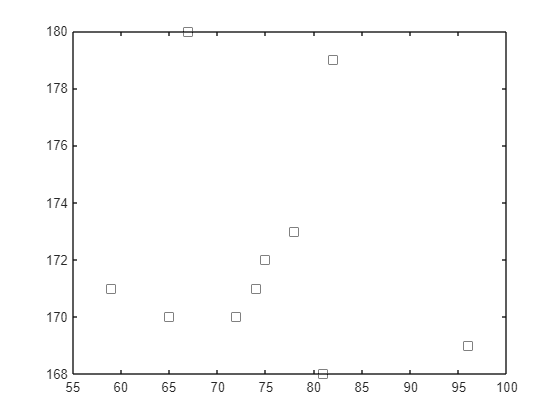

plot(mass_m, height_m, 'ks', 'Markersize',8) % il grafico viene automaticamente unito con una spezzata

Nota che tutti i plot creano dei nuovi grafici. Se vuoi disegnari i grafici uno sopra l'altro puoi utilizzare il comando *hold on*. Ricordati di utilizzare il comando *hold off* quando hai finito, in modo tale che i grafici successivi non continuino a sovrapporsi.

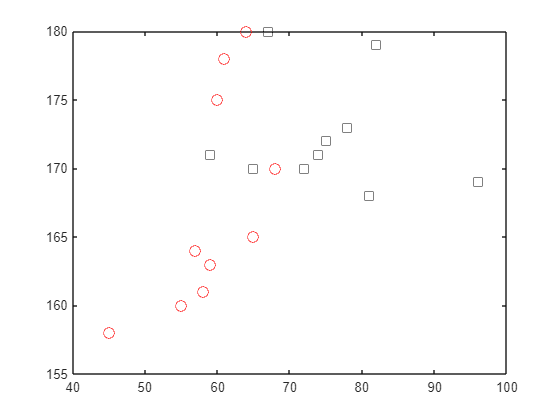

mass_f = [58 55 68 65 45 59 64 60 61 57];
height_f = [161 160 170 165 158 163 180 175 178 164];
plot(mass_m, height_m, "ks", 'MarkerSize', 8)
hold on
plot(mass_f, height_f, "ro", 'MarkerSize', 8)
hold off

### 3.2: Plottare funzioni

Per plottare funzioni ci sono diverse opzioni, la prima è usare il comando *plot* creando un vettore di punti denso in corrispondenza dell'intervallo sull'asse x in cui si vuole disegnare il grafico della funzione. Più punti ci sono nel vettore, meglio sarà rappresentato il grafico.

`Crea un vettore x di 100 punti da 0 a 2*pi`

`Con il comando plot(ascisse, ordinate) rappresenta la funzione sin(x) `

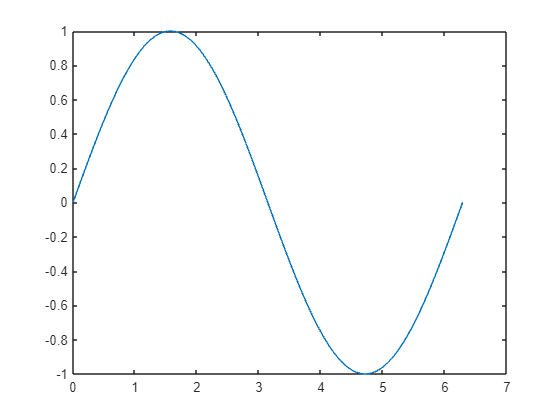

x = linspace(0, 2*pi, 100);
plot(x,sin(x))

Un metodo più comodo per plottare funzioni semplici o ben definite è definire le *anonymous function*, usando le **function handle** in combinazione con la funzione *fplot*. 

`anonymous function = @(lista variabili) espressione`

`utilizza il comando fplot(funzione, [a, b])`

`disegna `$x^3 +3\;x^2$ `(ricorda il .^) da -3 a 3`

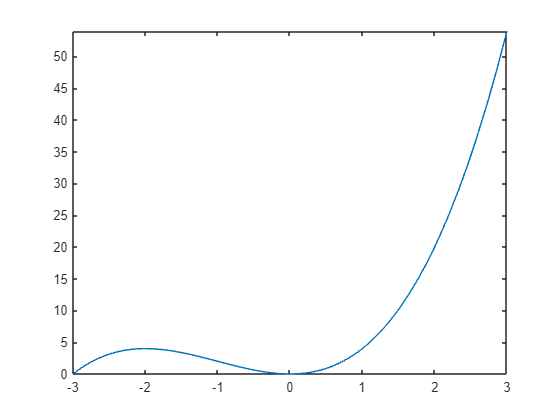

f = @(x) x.^3 + 3*x.^2;
fplot(f, [-3,3])

Vi lasciamo un esempio di plot con altre impostazioni che potrete utilizzare in futuro come template:

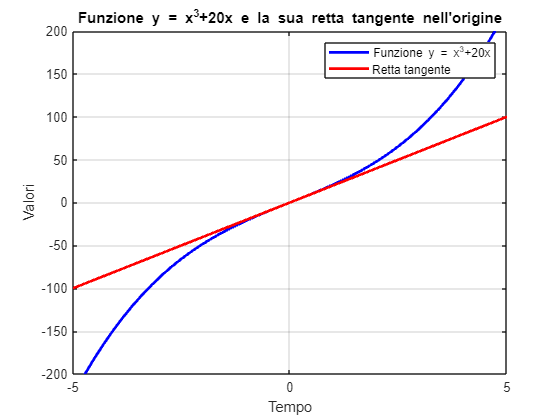

f = @(x) x.^3 +20.*x;

retta_tan = @(x) 20.*x;

figure()
fplot(f, 'b-', 'LineWidth', 2)
hold on 
fplot(retta_tan, 'r-', 'LineWidth', 2)
xlim([-5, 5])
ylim([-200, 200])
grid on
title("Funzione y = x^{3}+20x e la sua retta tangente nell'origine")
legend("Funzione y = x^{3}+20x", "Retta tangente")
xlabel('Tempo')
ylabel('Valori')
hold off

L'ultimo metodo è utilizzare il **calcolo simbolico**, come vedremo nel prossimo modulo.

## MODULO 4 (Calcolo simbolico, plot, solve, diff, int, limit)

**Symbolic Math Toolbox** offre funzioni per risolvere, rappresentare e manipolare equazioni di matematica simbolica. Il toolbox offre funzioni per aree comuni della matematica, come il calcolo, l'algebra lineare, le equazioni algebriche e differenziali, la semplificazione e la manipolazione delle equazioni, consentendo di eseguire analiticamente derivazioni, integrazioni, semplificazioni, trasformate e risoluzioni di equazioni. 

È un mondo un po' separato da quello in cui ci siamo mossi finora, in cui definiamo effettivamente delle incognite e **non **variabili informatiche. Ecco alcune applicazioni:

clc
clear all

syms x y

% Risoluzione di sistemi
eq1 = x + 2*y == 1

$$eq1 = x+2\,y=1$$

eq2 = 4*x + 5*y == 5

$$eq2 = 4\,x+5\,y=5$$

eqs = [eq1 eq2];
solve(eqs, [x y])

ans = struct with fields:
    x: 5/3
    y: -1/3



% Risoluzione di equazioni
solve(x^3 - 6*x^2 == 6 - 11*x)

$$ans = \left(\begin{array}{c} 1\\ 2\\ 3 \end{array}\right)$$

% Definire funzioni, derivare...
f = (1/(log(x))) * sqrt(x)/(x^2)

$$f = \frac{1}{x^{3/2}\,\log\left(x\right)}$$

df = diff(f, x) % guarda suggerimenti a destra (tre puntini)

$$df = -\frac{3}{2\,x^{5/2}\,\log\left(x\right)}-\frac{1}{x^{5/2}\,{\log\left(x\right)}^{2}}$$

% Compute simplified symbolic expression
simplifiedExpr = simplifyFraction(df)

$$simplifiedExpr = -\frac{3\,\log\left(x\right)+2}{2\,x^{5/2}\,{\log\left(x\right)}^{2}}$$

% ... calcolare sviluppo di Taylor, plottare
g = sin(x)

$$g = \sin\left(x\right)$$

var = taylor(g,x)

$$var = \frac{x^{5}}{120}-\frac{x^{3}}{6}+x$$

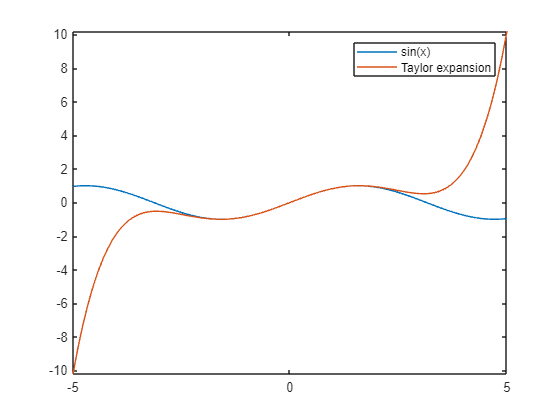

fplot(g)
hold on
fplot(var)
hold off

legend('sin(x)','Taylor expansion')

% ... calcolare integrali...
h(x) = log(x)

$$h(x) = \log\left(x\right)$$

h2(x) = 1/(log(x))

$$h2(x) = \frac{1}{\log\left(x\right)}$$


ph(x) = int(h,x)

$$ph(x) = x\,\left(\log\left(x\right)-1\right)$$

ph2(x) = int(h2,x)

$$ph2(x) = \mathrm{logint}\left(x\right)$$

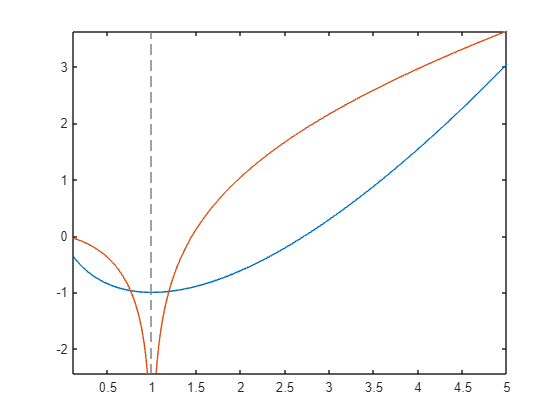


fplot(ph)
hold on
fplot(ph2)
hold off

% ... calcolare limiti ...
f2(x) = sin(x)/x

$$f2(x) = \frac{\sin\left(x\right)}{x}$$

limit(f2,0)

$$ans = 1$$


f3(x) = 1/x

$$f3(x) = \frac{1}{x}$$

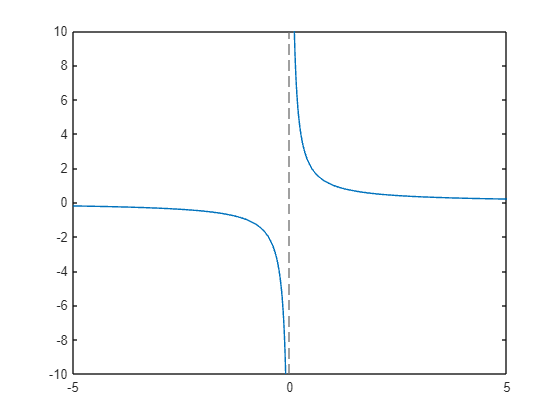

fplot(f3)

limit(f3,x,0, 'right')

$$ans = \infty$$

limit(f3,x,0,'left')

$$ans = -\infty$$

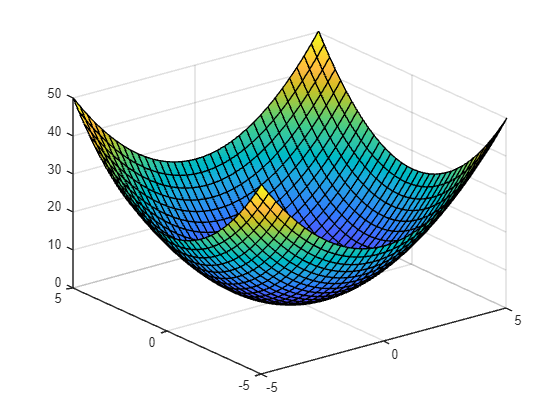

% ... Plottare superfici in 3D
fsurf(x^2 + y^2)

## MODULO 5 (If-else, for, while)

Anche in MATLAB come in tutti i linguaggi di programmazione è possibile utilizzare strutture di controllo quali:` if - else, for, while`.

La sintassi è la seguente:

z = randi([-5 5], 1)

z = 5

if z > 0
    disp('z positivo')
else 
    disp('z <= 0')
end

z positivo


for i=1:10
    disp(['il ciclo attuale è ',num2str(i)])
end

il ciclo attuale è 1
il ciclo attuale è 2
il ciclo attuale è 3
il ciclo attuale è 4
il ciclo attuale è 5
il ciclo attuale è 6
il ciclo attuale è 7
il ciclo attuale è 8
il ciclo attuale è 9
il ciclo attuale è 10



j=1;
while j<=10
     disp(['il ciclo attuale è ',num2str(j)])
     j = j+1;
end

il ciclo attuale è 1
il ciclo attuale è 2
il ciclo attuale è 3
il ciclo attuale è 4
il ciclo attuale è 5
il ciclo attuale è 6
il ciclo attuale è 7
il ciclo attuale è 8
il ciclo attuale è 9
il ciclo attuale è 10


Infine, vi lasciamo con la funzione `tic toc`, che permette di valutare il tempo impiegato per l'esecuzione della sezione di codice contenuto tra le due istruzioni.

tic
for i=1:10
    pause(0.1)
end
toc

Elapsed time is 2.840341 seconds.
